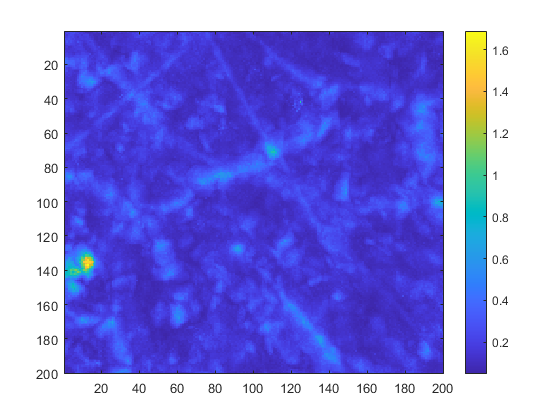

% Example of applying deconvolution on 3D optical-acoustic data

clear all

%Example of data

load('oa_3d_single.mat') 
figure; imagesc(squeeze(max(OA_3D,[],3))); colorbar;

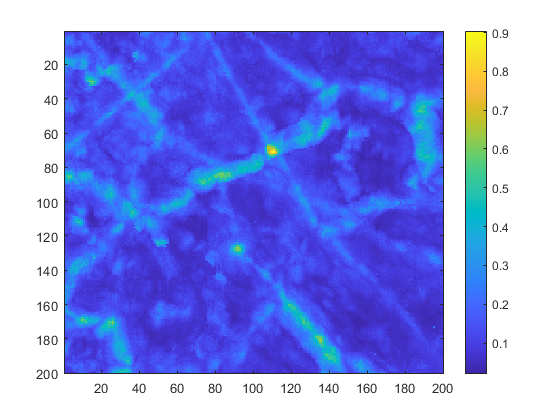

%Choosing a layer of 1500 microns for research

start =330;
delta1 =100;

figure; imagesc(squeeze(max(OA_3D(:,:,start:start+delta1),[],3))); colorbar;

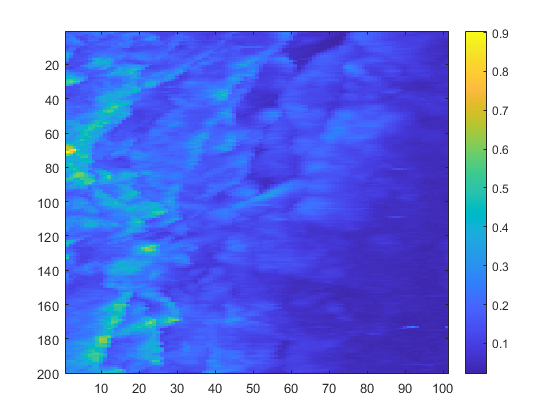

figure; imagesc(squeeze(max(OA_3D(:,:,start:start+delta1),[],2))); colorbar;

% Choosing an A-scan with a single source

xi =29 

xi = 29

yi =46

yi = 46

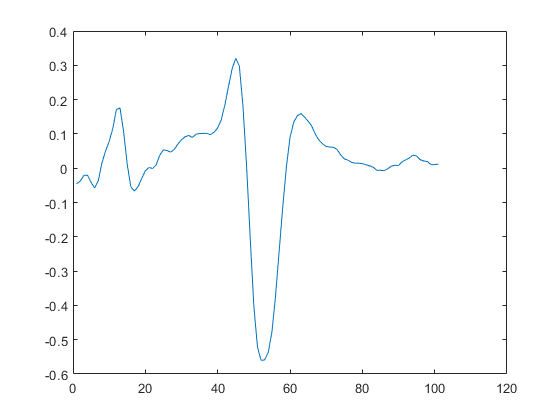



Ascan2 = squeeze(OA_3D(xi, yi, start:start+delta1)); 
figure;
plot(Ascan2)

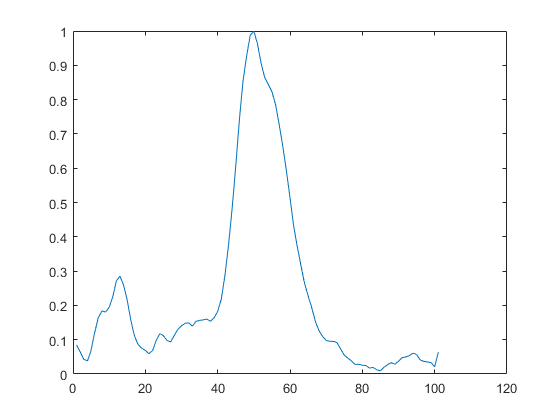


Ascan2_hilb = abs(hilbert(Ascan2))/max(abs(hilbert(Ascan2)));
figure;
plot(Ascan2_hilb)

%Illustrations for the selecting a training A-scan

[pcs,lcs]=max(Ascan2_hilb); %find Max value

delta = 31  %width of peak

delta = 31

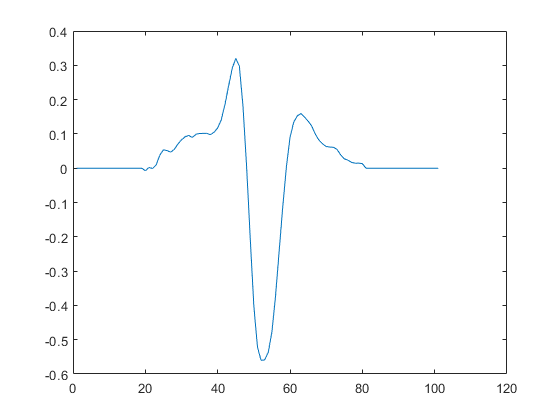


Ascan3= Ascan2;
Ascan3(1:lcs-delta)=0; % zeroing width of peak
Ascan3(lcs+delta:end)=0;

figure;
plot(Ascan3)

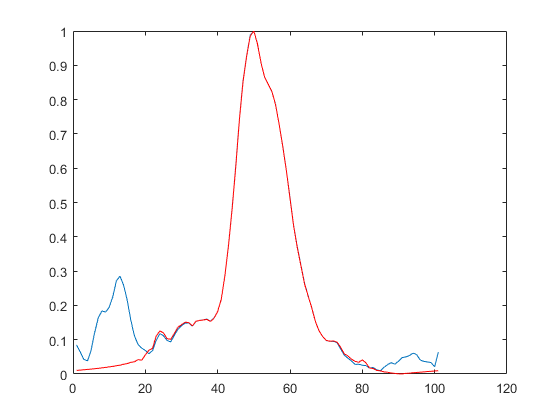


figure
plot(Ascan2_hilb)
hold on
plot(abs(hilbert(Ascan3))/max(abs(hilbert(Ascan3))),'r');
hold off

%Running deconvolution params search using GPU

OA_3D_deconv=TRDeconv_GPU(OA_3D,xi,yi,330,430,delta);

delta = 31

N0 = 16

N1 = 15

N2 = 10

N3 = 15

N1 = 10

N2 = 8

N3 = 11

N1 = 8

N2 = 8

N3 = 8

Elapsed time is 0.560410 seconds.



load('TRD_var.mat')

bet=bet_f     %optimal value of the regularization parameter

bet = 0.0475

C=compr       %maximum value of the compression rate

C = 50

k=nk          %completed iterations

k = 3

F=FdeconvNew  %optimal kernel

F =    -1.5620    2.8660   -1.3601


%Speed test on array 200x200x100

M1=OA_3D(:,:,330:429);

Fdeconv3d =reshape(F, 1, 1, 3); 

%Move kernel to gpu
Fdeconv3d_gpu = gpuArray(Fdeconv3d);

%Test CPU convolution
disp 'Test CPU convolution'

Test CPU convolution


tic
M2 = convn(M1,Fdeconv3d, 'SAME');
toc

Elapsed time is 0.061168 seconds.



%Test GPU convolution
disp 'Test GPU convolution'

Test GPU convolution


%Compiling GPU kernels
M1_gpu = gpuArray(M1);
tic
M2_gpu = convn(M1_gpu,Fdeconv3d_gpu, 'SAME');
toc

Elapsed time is 0.007687 seconds.


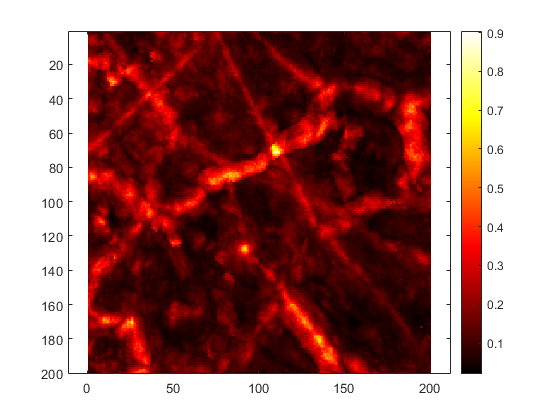

%Image comparison

start = 330;
delta1 = 100;
figure; imagesc(squeeze(max(OA_3D(:,:,start:start+delta1),[],3))); colorbar; axis equal; colormap('hot'); %до

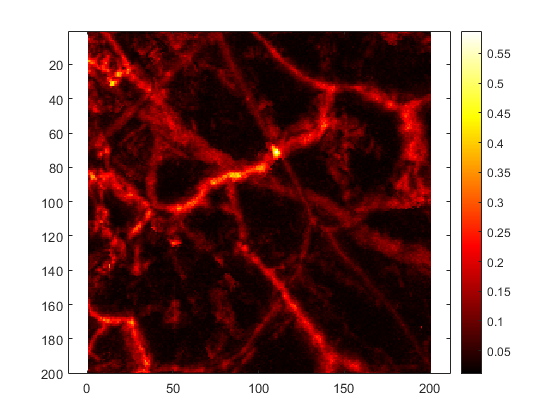

figure; imagesc(squeeze(max(OA_3D_deconv(:,:,start:start+delta1),[],3))); colorbar; axis equal; colormap('hot');% после

%Comparing z-scan after deconvolution
xv=29

xv = 29

yv=42

yv = 42

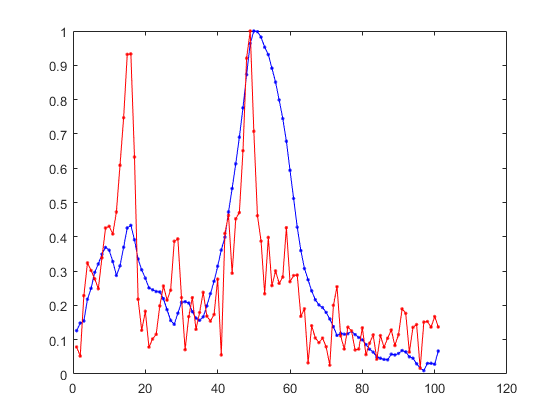


SC1_=squeeze(abs(hilbert(OA_3D(xv, yv, start:start+delta1))))/max(squeeze(abs(hilbert(OA_3D(xv, yv, start:start+delta1)))));
SC2_=squeeze(abs(hilbert(OA_3D_deconv(xv, yv, start:start+delta1))))/max(squeeze(abs(hilbert(OA_3D_deconv(xv, yv, start:start+delta1)))));

figure;
plot(SC1_,'.-b')
hold on
%figure;
plot(SC2_,'.-r')
hold off


%Calc compression rate of z-scan

NSC1=0;
NSC2=0;

for i=1:1:81
    
    if  SC1_(i+20)-0.5<0
        NSC1=NSC1;
        else
        NSC1=NSC1+1;                                 
    end
    if  SC2_(i+20)-0.5<0
        NSC2=NSC2;
        else
        NSC2=NSC2+1;
    end
end
                      
N1=NSC1

N1 = 18

N2=NSC2

N2 = 4

Compr_Z=100*(N1-N2)/N1

Compr_Z = 77.7778

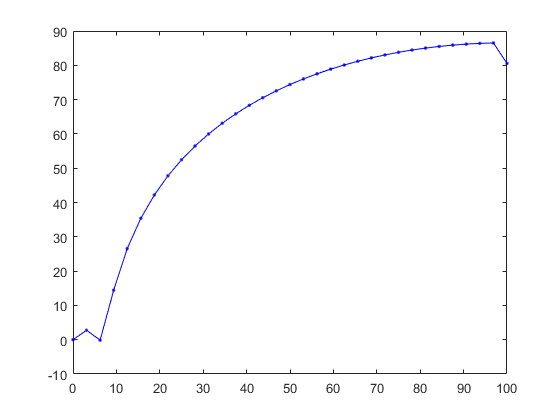


%Deconv FR calculation
t = 0:0.001:1-0.001;
Fs = 200000000; % sampling freq 200mhz

[pun,fr] = periodogram(F,[],64,Fs);

x=fr/1e6;
y=20*log10(pun/pun(1));

figure;
plot(x,y, '.b-'),